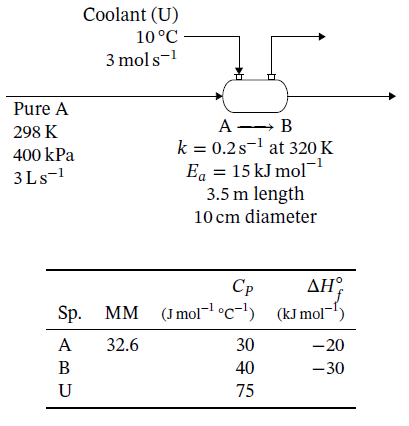

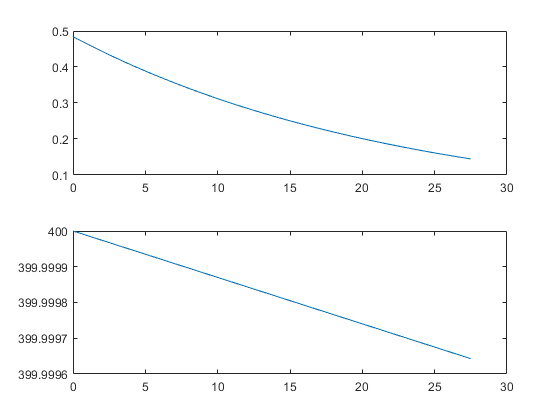

% Isothermal
T0 = 298; % K
P0 = 400; % kPa
v0 = 3; % L/s
nA0 = P0*v0/(8.314*T0); % 8.314 L-kPa/(mol-K)
Vmax = 0.25*pi*(10/100)^2*3.5*1000; % m3 -> L
Y0 = [nA0; 0; P0]; % [nA; nB; P], [mol/s mol/s kPa]
[V, Y] = ode45(@myODE, [0 Vmax], Y0);
nA = Y(:, 1); % mol/s
nB = Y(:, 2); % mol/s
P = Y(:, 3); % kPa
subplot 211; plot(V, nA);
subplot 212; plot(V, P);

function dYdV = myODE(V, Y)
nA = Y(1); % mol/s
nB = Y(2); % mol/s
P = Y(3); % kPa

k = 0.2*exp(15000/8.314*(1/320-1/298)); % (3.10)
nT = nA+nB; % mol/s

R = 8.314; % L-kPa/mol-K
T = 298; % K
P = 400; % kPa
v = nT*R*T/P; % IGL: nT*R*T/P, or (5.5)

r = k*nA/v; % mol/L-s, elementary
dnAdV = -r; % mol/L-s, (7.1)
dnBdV = r; % mol/L-s, (7.1)

% Pressure drop
d = 0.1; % m
mT = 32.6*(nA + nB)/1000; % g/s -> kg/s
Re = 4*mT/(pi * d * 1e-5); % unitless
f = 0.0791*Re.^(-0.25); % unitless
dPdV = -v*f*128*mT./(pi^3 * d.^7)/1000/1000/1000; % kPa/L 

dYdV = [dnAdV; dnBdV; dPdV]; % mol/L-s
end